## データ取り込み

clear, clc, close all
list = dir('*.csv');
numFiles = length(list);
Mx = cell(numFiles,2); % インポート用のセル

## キャリブレーションの平均値取得

% time gaze_X gaze_Y gaze_Z LookAt
Calib = readmatrix(list(1).name);
posNum = 5; % キャリブレーションの点数
CalibCell = cell(4,5);
PosStr = ["Center";"Left";"Bottom";"Right";"Top"];
DescStr = ["data" "x_mean" "x_std" "y_mean" ...
    "y_std" "z_mean" "z_std" "Position"]
for i = 1:posNum
    % ターゲットを見ている間のデータを抽出
    CalibCell{i,1} = Calib(Calib(:,5)==(i-1),:);
    for k = 2:4
        CalibCell{i,2+k} = mean(CalibCell{i,1}(:,k));
        CalibCell{i,k} = std(CalibCell{i,1}(:,k));
    end
    CalibCell{i,5} = PosStr(i,1);
end
CalibCell{i+1,:} = DescStr;
% 点数を統一する処理が必要。点数の真ん中から100点とる？


## 実験データの取得・整理

% 実験条件の名前
condName = ["None";"Vision";"Haptic";"Vis_Hap"];
find(condName=="Vision");
condCol = 11; % データ内に条件が記載された列
for i = 2:numFiles
    tmpCell = readcell(list(i).name);
    idx = find(condName == tmpCell{2,condCol});
    Mx{idx,1} = readmatrix(list(i).name);
    % 結果が0/1の試行をカウント
    Mx{idx,2} = size(find(Mx{idx,1}(:,12) == 0),1);
    Mx{idx,3} = size(find(Mx{idx,1}(:,12) == 1),1);
    % 説明追記
    Mx{idx,4} = condName(idx,1);
end
descStr = ["data";"Miss";"Success";"Condition"];
for i = 1:size(descStr,1)
    Mx{size(condName,1)+1,i} = descStr(i,1);
end


## 視線グラフ化

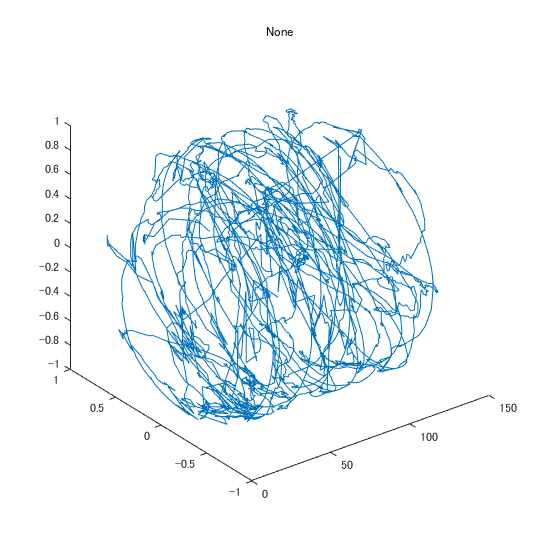

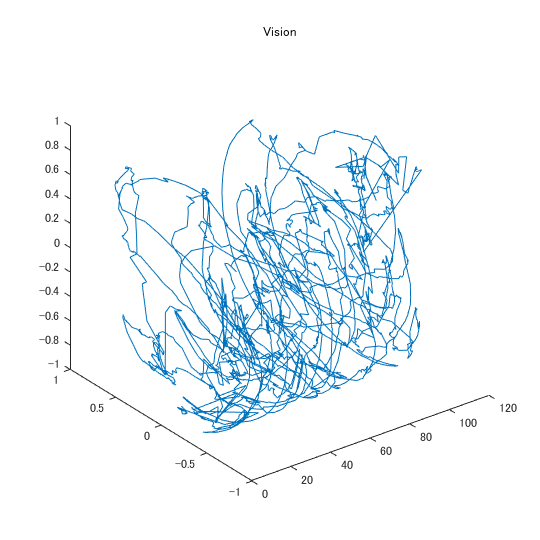

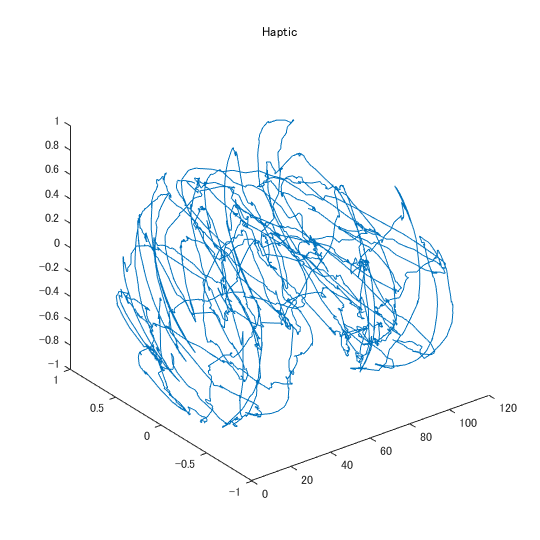

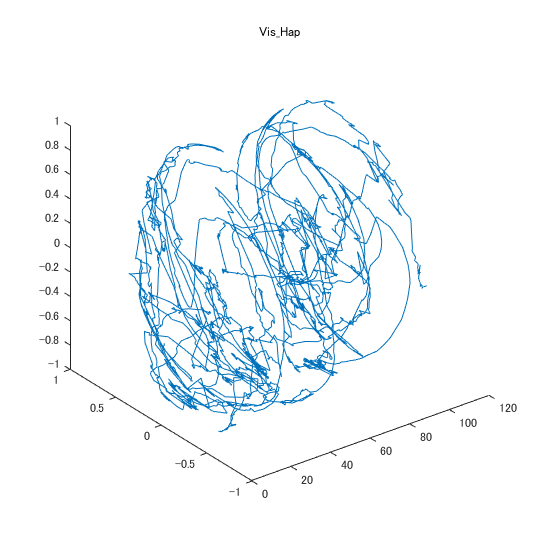

% time gaze_X_Y_Z camRot_X_Y_Z camPos_X_Y_Z	condition
close all;
for i = 1:size(condName,1)
    condNum = i;
    gaze = Mx{condNum,1}(:,1:3);
    t = gaze(:,1);
    x = gaze(:,2);
    y = gaze(:,3);

    %     視線散布図追加
%     figure('Position',[0 -700 540 540])
%     hold on
%     scatter(x,y,'SizeData',1);
%     %     キャリブレーション結果の追加
%     xx = [CalibCell{:,2}];
%     yy = [CalibCell{:,3}];
%     scatter(xx, yy,'filled','r');
%     title(condName(condNum,1),'interpreter','none');
%     set(gcf, 'visible', 'on')
%     ax = gca; % current axes
%     ax.FontSize = 12;
%     ax.FontName = 'tahoma';
%     hold off
%     saveas(gcf,strcat('scatter',condName(condNum,1),'.png'));

    %     時系列データ込み3次元プロット
    figure('Position',[0 -700 540 540])
    plot3(t,x,y);
    set(gcf, 'visible', 'on')
    title(condName(condNum,1),'interpreter','none');
end